% ----------------- %
% Projet 1 SLAM EKF %
% ----------------- %

clear all; close all;


## Creation de la carte

Le but de cette partie est de générer une carte avec des amers dont la position est aléatoie.

La position du premier amer est entrée, les écarts en x et y des amers sont donnés, la position des 7 autres amers est calculés. Ce calcul donne la position moyenne des amers

Une fois la position moyenne de chaque amer calculée, la position réelle des amers est tirée suivant une gaussienne, la dispersion d'un amer autour de sa position moyenne est la même pour tous les amers. 

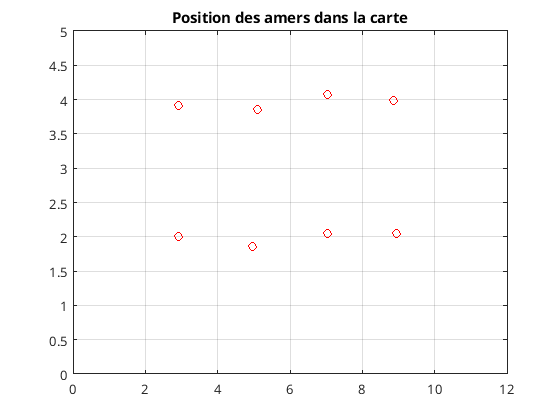

%Distances entre les amers
distXamer = 2;
disYamer = -2;

%Position des amers, vecteur de position des amers :
%    - elements impairs : position en X de l'amer 2*i-1
%    - elements pairs : position en Y de l'amer 2*i
amer=[3 ;4];

for i=2:4
    amer(2*i-1) = amer(2*i-3)+distXamer;
    amer(2*i) = amer(2);
end
for i=5:8
    amer(2*i-1) = amer(2*i-9);
    amer(2*i) = amer(2)+disYamer;
end
%Ajout de bruit dans la position des amers
dispAmers = 2/3*10^(-2) *ones(1,16);
amer = amer + chol(diag(dispAmers))'*randn(16,1);

%Affichage des amers
figure(1)
plot(amer(1:2:16), amer(2:2:16), 'or')
grid on 
axis([0 12 0 5])
title("Position des amers dans la carte")

## Génération de la trajectoire du robot

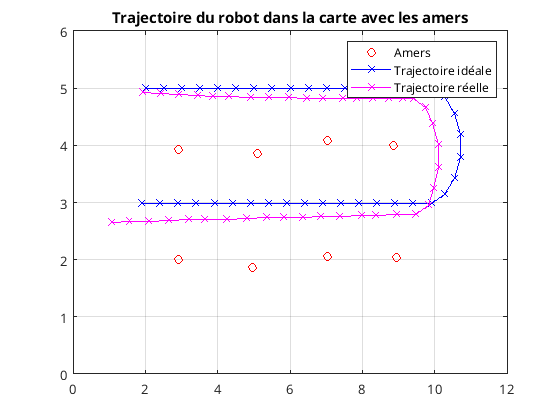

%Nombre d'instants
N1 = 15;
N2 = 8;
N3 = 17;
N = N1+N2+N3;

%Genération de la position du robot 
%Position initiale
Xr(:,1) = [2;5;0];
%Ajout du bruit
dispX0 = [1/3*10^(-2) 1/3*10^(-2) .0005/3*10];
Xrb(:,1) = Xr(:,1) + chol(diag(dispX0))'*randn(3,1);
%Vecteur de commande
for i=1:N1
    U(:,i)=[0.5;0;0];
end
for i=N1+1:N1+N2
    U(:,i)=[0.4;0;-pi/N2];
end
for i=N1+N2+1:N1+N2+N3
    U(:,i)=[0.5;0;0];
end
%Boucle de generation de la trajectoire
for i=2:N
    Xr(:,i) = dynRob(Xr(:,i-1), U(:,i-1));
    Xrb(:,i) = dynRob(Xrb(:,i-1), U(:,i-1));
    %Ajout du bruit
    dispX = [1/3*10^(-2) 1*10^(-7) .1/3*10^(-3)];
    Xrb(:,i) = Xrb(:,i) + chol(diag(dispX))'*randn(3,1);
end

%Affichage de la trajectoire du robot 
figure(2)
plot(amer(1:2:16), amer(2:2:16), 'or')
hold on
plot(Xr(1,:), Xr(2,:), 'x-b')
plot(Xrb(1,:), Xrb(2,:), 'x-m')
hold off
axis([0 12 0 6])
grid on
title("Trajectoire du robot dans la carte avec les amers")
legend('Amers', 'Trajectoire idéale', 'Trajectoire réelle')

## Generation des données de vision 

distVision = 2;
%Pas de mesures a l'etat initial 
z(:,1) = NaN * ones(2*8,1);

%Genrations de mesures pour les instants 2 a N
for k=2:N
    for j=1:8
        z(2*j-1,k) = sqrt((amer(2*j-1)-Xrb(1,k))^2+(amer(2*j)-Xrb(2,k))^2);
        z(2*j,k) = atan2((amer(2*j)-Xrb(2,k)),(amer(2*j-1)-Xrb(1,k)))-Xrb(3,k);
    end
end

%Suppression des données hors du champ de vision 
for k=2:N
    for j=1:8
        if(z(2*j-1,k)>distVision)
            z(2*j-1,k) = NaN;
            z(2*j,k) = NaN;
        end
    end
end
%Affichage du champ de vision
for k=1:N
    figure(3)
    plot(amer(1:2:16), amer(2:2:16), 'or');
    grid on
    hold on
    axis([0 15 0 15]);
    plot(Xrb(1,k), Xrb(2,k), 'xb');
    cercle(Xrb(1:2,k), distVision, 'b');
    hold off
    title('Evolution du champ de vision du robot')
    drawnow
    pause(0.25)
end

% Ajout du bruit sur les mesures 
Rv = diag([.1^2 .1^2 .1^2 .1^2 .1^2 .1^2 .1^2 .1^2 .1^2 .1^2 .1^2 .1^2 .1^2 .1^2 .1^2 .1^2]);
Zbruit = cell(1,N);
for i = 1:N
    Zbruit{i} = z(:,i) + chol(Rv)'*randn(16,1);
end

## Données pour le filtrage

% Creation de la structure d'etat reel 
Xreel = cell(1, N);
for i = 1:N 
    Xreel{i} = [Xrb(:,i) ; amer];
end

%Creation des structures de donnees pour le filtre 
Xpred = cell(1,N);
Xest = cell(1, N);
Ppred = cell(1,N);
Pest = cell(1,N);

%Matrice de covariance des bruits (Rv deja creee)
PX0 = diag([dispX0 dispAmers]);
Qw = diag([dispX (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2]);

## Filtrage

% Initialisation du filtre 
Xpred{1} = [Xrb(:, 1)];
Ppred{1} = NaN;
Xest{1} = [Xrb(:, 1)];
Pest{1} = diag([dispX0 dispAmers]);

%Matrice Fk, termes constants 
Fk = zeros(19);
Fk(1,1) = 1;
Fk(2,2) = 1;
Fk(3,3) = 1;


% figure(4)
% plot(amer(1:2:16), amer(2:2:16), 'or');
% hold on 
% title("Affichage de la position estimée du robot")
% axis([0 12 0 6]);
% grid on

%Boucle de simulation du filtre + affichage des données "en temps reel" avec l'etat reel des amers de du robot + elipse de bruit 
for k = 2:N
    %Prediction 
    Xpred{k} = dynRob(Xest{k-1}, U(:,k-1));
    
    %Mise a jour des termes variables de Fk
    Fk(3,1) = -U(1,k-1)*sin(Xest{k-1}(3))-U(2,k-1)*cos(Xest{k-1}(3));
    Fk(3,2) = U(1,k-1)*cos(Xest{k-1}(3))-U(2,k-1)*sin(Xest{k-1}(3));
    Ppred{k} = Fk*Pest{k-1}*Fk' + Qw;
    
    %Mise à jour
    %Idee pour la mise a jour. A chaque iteration, parcourir l'ensemble des
    %mesures de deux en deux (de 1 jusqu'a 15). Pour chaque element non
    %NaN, ajouter l'element dans un vecteur zutile + ajouter l'element
    %correspondant dans la jacobienne. 
    indZ = 1;
    for i=1:2:16
        %reformlation des mesures pour supprimer les NaN
        if ~isnan(Zbruit{k}(i))
            Zutile(indZ:indZ+1, 1) = Zbruit{k}(i:i+1);
            H(indZ:indZ+1, :) = zeros(2, 19);
            %Calcul des dérivée de h et ajout des termes dans les cases
            %correspondantes 
            indZ = indZ+2;
        end
        %Ici : mise a jour 
    end
    Xest{k} = Xpred{k};
    Pest{k} = Ppred{k};
    
    %On efface la variable ne pas prendre en compte de mauuvises donnees a
    %la prochaine iteration
    clearvars Zutile
    
    %Affichage
%     plot(Xpred{k}(1),Xpred{k}(2), 'xb')
%     ellipse(Xpred{k}(1:2), Ppred{k}(1:2, 1:2), 'b');
%     drawnow
%     pause(0.25)
end

    1.1055
   -1.0079
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN



Zreel =     1.1055
   -1.0079


    0.8600
   -1.6931
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN



Zreel =     0.8600
   -1.6931


    1.0043
   -2.0083
    1.8609
   -0.5093
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN



Zreel =     1.0043
   -2.0083


Zreel =     1.0043
   -2.0083
    1.8609
   -0.5093


    1.4555
   -2.4175
    1.5610
   -0.5931
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN



Zreel =     1.4555
   -2.4175
    1.8609
   -0.5093


Zreel =     1.4555
   -2.4175
    1.5610
   -0.5931


    1.5487
   -2.5115
    1.3050
   -0.7278
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN



Zreel =     1.5487
   -2.5115
    1.5610
   -0.5931


Zreel =     1.5487
   -2.5115
    1.3050
   -0.7278


       NaN
       NaN
    1.0350
   -1.4133
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN



Zreel =     1.0350
   -1.4133
    1.3050
   -0.7278


       NaN
       NaN
    1.1056
   -1.8594
    1.7407
   -0.4608
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN



Zreel =     1.1056
   -1.8594
    1.3050
   -0.7278


Zreel =     1.1056
   -1.8594
    1.7407
   -0.4608


       NaN
       NaN
    1.3874
   -2.1298
    1.2660
   -0.5423
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN



Zreel =     1.3874
   -2.1298
    1.7407
   -0.4608


Zreel =     1.3874
   -2.1298
    1.2660
   -0.5423


       NaN
       NaN
    1.8420
   -2.4267
    1.0912
   -0.9085
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN



Zreel =     1.8420
   -2.4267
    1.2660
   -0.5423


Zreel =     1.8420
   -2.4267
    1.0912
   -0.9085


       NaN
       NaN
       NaN
       NaN
    0.6940
   -1.4631
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN



Zreel =     0.6940
   -1.4631
    1.0912
   -0.9085


       NaN
       NaN
       NaN
       NaN
    0.9115
   -2.2643
    1.7300
   -0.4503
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN



Zreel =     0.9115
   -2.2643
    1.0912
   -0.9085


Zreel =     0.9115
   -2.2643
    1.7300
   -0.4503


       NaN
       NaN
       NaN
       NaN
    0.9079
   -2.3032
    1.1034
   -0.6370
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN



Zreel =     0.9079
   -2.3032
    1.7300
   -0.4503


Zreel =     0.9079
   -2.3032
    1.1034
   -0.6370


       NaN
       NaN
       NaN
       NaN
    1.4833
   -2.5476
    0.9377
   -0.9654
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN



Zreel =     1.4833
   -2.5476
    1.1034
   -0.6370


Zreel =     1.4833
   -2.5476
    0.9377
   -0.9654


       NaN
       NaN
       NaN
       NaN
    1.8760
   -2.4085
    0.8515
   -1.4023
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN



Zreel =     1.8760
   -2.4085
    0.9377
   -0.9654


Zreel =     1.8760
   -2.4085
    0.8515
   -1.4023


       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
    0.7254
   -1.8423
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN



Zreel =     0.7254
   -1.8423
    0.8515
   -1.4023


       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
    0.7105
   -1.7040
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN



Zreel =     0.7105
   -1.7040
    0.8515
   -1.4023


       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
    1.0466
   -1.6076
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN



Zreel =     1.0466
   -1.6076
    0.8515
   -1.4023


       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
    1.3101
   -1.4943
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN



Zreel =     1.3101
   -1.4943
    0.8515
   -1.4023


       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
    1.2742
   -1.5167
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN



Zreel =     1.2742
   -1.5167
    0.8515
   -1.4023


       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
    1.3008
    4.8474
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
    1.9349
   -0.3205



Zreel =     1.3008
    4.8474
    0.8515
   -1.4023


Zreel =     1.3008
    4.8474
    1.9349
   -0.3205


       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
    1.3302
    5.0578
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
    1.4398
    0.0334



Zreel =     1.3302
    5.0578
    1.9349
   -0.3205


Zreel =     1.3302
    5.0578
    1.4398
    0.0334


       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
    1.5887
    5.0211
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
    1.0533
    0.3511



Zreel =     1.5887
    5.0211
    1.4398
    0.0334


Zreel =     1.5887
    5.0211
    1.0533
    0.3511


       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
    1.4964
    5.1885
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
    0.8378
    0.9088



Zreel =     1.4964
    5.1885
    1.0533
    0.3511


Zreel =     1.4964
    5.1885
    0.8378
    0.9088


       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
    1.3937
    4.5392
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
    0.6817
    1.4248



Zreel =     1.3937
    4.5392
    0.8378
    0.9088


Zreel =     1.3937
    4.5392
    0.6817
    1.4248


       NaN
       NaN
       NaN
       NaN
    1.8693
    5.5502
    1.3766
    4.3244
       NaN
       NaN
       NaN
       NaN
    1.3862
    0.3329
    0.9071
    2.2731



Zreel =     1.8693
    5.5502
    0.6817
    1.4248


Zreel =     1.8693
    5.5502
    1.3766
    4.3244


Zreel =     1.8693
    5.5502
    1.3766
    4.3244
    1.3862
    0.3329


Zreel =     1.8693
    5.5502
    1.3766
    4.3244
    1.3862
    0.3329
    0.9071
    2.2731


       NaN
       NaN
       NaN
       NaN
    1.6570
    5.4223
    1.4577
    4.0736
       NaN
       NaN
       NaN
       NaN
    1.1334
    0.7551
    1.1631
    2.4830



Zreel =     1.6570
    5.4223
    1.3766
    4.3244
    1.3862
    0.3329
    0.9071
    2.2731


Zreel =     1.6570
    5.4223
    1.4577
    4.0736
    1.3862
    0.3329
    0.9071
    2.2731


Zreel =     1.6570
    5.4223
    1.4577
    4.0736
    1.1334
    0.7551
    0.9071
    2.2731


Zreel =     1.6570
    5.4223
    1.4577
    4.0736
    1.1334
    0.7551
    1.1631
    2.4830


       NaN
       NaN
       NaN
       NaN
    1.3565
    4.8692
    1.9140
    3.6857
       NaN
       NaN
       NaN
       NaN
    0.8276
    1.2099
    1.7719
    2.7871



Zreel =     1.3565
    4.8692
    1.4577
    4.0736
    1.1334
    0.7551
    1.1631
    2.4830


Zreel =     1.3565
    4.8692
    1.9140
    3.6857
    1.1334
    0.7551
    1.1631
    2.4830


Zreel =     1.3565
    4.8692
    1.9140
    3.6857
    0.8276
    1.2099
    1.1631
    2.4830


Zreel =     1.3565
    4.8692
    1.9140
    3.6857
    0.8276
    1.2099
    1.7719
    2.7871


       NaN
       NaN
       NaN
       NaN
    1.2848
    4.4525
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
    0.6139
    1.8115
       NaN
       NaN



Zreel =     1.2848
    4.4525
    1.9140
    3.6857
    0.8276
    1.2099
    1.7719
    2.7871


Zreel =     1.2848
    4.4525
    0.6139
    1.8115
    0.8276
    1.2099
    1.7719
    2.7871


       NaN
       NaN
    1.7485
    5.5763
    1.4233
    4.3079
       NaN
       NaN
       NaN
       NaN
    1.6698
    0.6531
    1.0463
    2.4773
       NaN
       NaN



Zreel =     1.7485
    5.5763
    0.6139
    1.8115
    0.8276
    1.2099
    1.7719
    2.7871


Zreel =     1.7485
    5.5763
    1.4233
    4.3079
    0.8276
    1.2099
    1.7719
    2.7871


Zreel =     1.7485
    5.5763
    1.4233
    4.3079
    1.6698
    0.6531
    1.7719
    2.7871


Zreel =     1.7485
    5.5763
    1.4233
    4.3079
    1.6698
    0.6531
    1.0463
    2.4773


       NaN
       NaN
    1.4340
    5.2004
    1.8455
    3.7712
       NaN
       NaN
       NaN
       NaN
    1.1637
    0.8447
    1.3018
    2.7017
       NaN
       NaN



Zreel =     1.4340
    5.2004
    1.4233
    4.3079
    1.6698
    0.6531
    1.0463
    2.4773


Zreel =     1.4340
    5.2004
    1.8455
    3.7712
    1.6698
    0.6531
    1.0463
    2.4773


Zreel =     1.4340
    5.2004
    1.8455
    3.7712
    1.1637
    0.8447
    1.0463
    2.4773


Zreel =     1.4340
    5.2004
    1.8455
    3.7712
    1.1637
    0.8447
    1.3018
    2.7017


       NaN
       NaN
    1.0765
    5.1026
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
    1.0335
    1.0737
    1.8497
    2.7081
       NaN
       NaN



Zreel =     1.0765
    5.1026
    1.8455
    3.7712
    1.1637
    0.8447
    1.3018
    2.7017


Zreel =     1.0765
    5.1026
    1.0335
    1.0737
    1.1637
    0.8447
    1.3018
    2.7017


Zreel =     1.0765
    5.1026
    1.0335
    1.0737
    1.8497
    2.7081
    1.3018
    2.7017


       NaN
       NaN
    1.2844
    4.4533
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
    0.9624
    1.8894
       NaN
       NaN
       NaN
       NaN



Zreel =     1.2844
    4.4533
    1.0335
    1.0737
    1.8497
    2.7081
    1.3018
    2.7017


Zreel =     1.2844
    4.4533
    0.9624
    1.8894
    1.8497
    2.7081
    1.3018
    2.7017


    1.7425
    5.5377
    1.3715
    4.0696
       NaN
       NaN
       NaN
       NaN
    1.5995
    0.4201
    1.0369
    2.4096
       NaN
       NaN
       NaN
       NaN



Zreel =     1.7425
    5.5377
    0.9624
    1.8894
    1.8497
    2.7081
    1.3018
    2.7017


Zreel =     1.7425
    5.5377
    1.3715
    4.0696
    1.8497
    2.7081
    1.3018
    2.7017


Zreel =     1.7425
    5.5377
    1.3715
    4.0696
    1.5995
    0.4201
    1.3018
    2.7017


Zreel =     1.7425
    5.5377
    1.3715
    4.0696
    1.5995
    0.4201
    1.0369
    2.4096


    1.5247
    5.4696
    1.6166
    3.8103
       NaN
       NaN
       NaN
       NaN
    0.9469
    0.8169
    1.6974
    2.5853
       NaN
       NaN
       NaN
       NaN



Zreel =     1.5247
    5.4696
    1.3715
    4.0696
    1.5995
    0.4201
    1.0369
    2.4096


Zreel =     1.5247
    5.4696
    1.6166
    3.8103
    1.5995
    0.4201
    1.0369
    2.4096


Zreel =     1.5247
    5.4696
    1.6166
    3.8103
    0.9469
    0.8169
    1.0369
    2.4096


Zreel =     1.5247
    5.4696
    1.6166
    3.8103
    0.9469
    0.8169
    1.6974
    2.5853


    1.3005
    5.0415
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
    0.5995
    1.1319
    1.8206
    2.8187
       NaN
       NaN
       NaN
       NaN



Zreel =     1.3005
    5.0415
    1.6166
    3.8103
    0.9469
    0.8169
    1.6974
    2.5853


Zreel =     1.3005
    5.0415
    0.5995
    1.1319
    0.9469
    0.8169
    1.6974
    2.5853


Zreel =     1.3005
    5.0415
    0.5995
    1.1319
    1.8206
    2.8187
    1.6974
    2.5853


    1.2185
    4.5919
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
    0.5683
    1.9374
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN



Zreel =     1.2185
    4.5919
    0.5995
    1.1319
    1.8206
    2.8187
    1.6974
    2.5853


Zreel =     1.2185
    4.5919
    0.5683
    1.9374
    1.8206
    2.8187
    1.6974
    2.5853


    1.6277
    4.0792
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
    1.2111
    2.3490
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN



Zreel =     1.6277
    4.0792
    0.5683
    1.9374
    1.8206
    2.8187
    1.6974
    2.5853


Zreel =     1.6277
    4.0792
    1.2111
    2.3490
    1.8206
    2.8187
    1.6974
    2.5853


    1.8677
    3.8280
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
    1.3686
    2.8217
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN



Zreel =     1.8677
    3.8280
    1.2111
    2.3490
    1.8206
    2.8187
    1.6974
    2.5853


Zreel =     1.8677
    3.8280
    1.3686
    2.8217
    1.8206
    2.8187
    1.6974
    2.5853


       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
    2.0067
    2.8178
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN



Zreel =     2.0067
    2.8178
    1.3686
    2.8217
    1.8206
    2.8187
    1.6974
    2.5853


## Estimation de la qualité du filtre 